**Coherence with hilbert transform**

**1 Read in trials**

data60misc4 : yellow tagged at 60 Hz (photodiode 1) 

data60misc5: teal tagged at 60 Hz (photodiode 2) 

data67misc4: yellow tagged at 67 Hz (photodiode 1) 

data67misc5: teal tagged at 67 Hz (photodiode 2)

**2 Calculate coherence and power spectral density**

**add zero padding to the end of each trial (after psd has been calculated) -> avoid losing data**

% foi = 52:2:80
% frqwdt = 2
% diodelabel: either 'MISC004' or 'MISC005'
% data: one of the above
%function [coh_spct, psd_meg, psd_misc] = kd_coh_hilb(data, foi, frqwdth, diodelabel)

cfg = [];
cfg.bpfilter    = 'yes';
cfg.hilbert     = 'complex';
cfg.keeptrials  = 'yes';
idxmisc = find(strcmp(data.label,diodelabel));
padl = 8;       % length of padding in sec

% loop over frequencies & hilbert transform
for f = 1:length(foi)
    % bp filter
    cfg.bpfreq = [foi(f)-frqwdth foi(f)+frqwdth];

    data_foi = ft_preprocessing(cfg,data);
    

    % for each channel
    for c = 1:length(data.label)
        meg = [];
        misc = [];
        
        meg_pad = [];
        misc_pad = [];
        csd_pad = [];
        % loop over trials
        for t = 1:length(data.trial)
            
            % select current time series
            meg= data_foi.trial{t}(c,:);
            misc = data_foi.trial{t}(idxmisc,:);
            
            % power spectral density in this trial
            psd_meg_trl = meg.*conj(meg);
            psd_misc_trl = misc.*conj(misc);
            
            % cross-spectral density in this trial
            csd_meg_misc_trl = meg .* conj(misc);
            
            % zero padding
            padzero = zeros(1,uint16(padl*data.fsample - length(psd_meg_trl)));
            
            % add to matrix trial x time
            meg_pad(t,:) = [psd_meg_trl, padzero];
            misc_pad(t,:) = [psd_misc_trl, padzero];
            csd_pad(t,:) = [csd_meg_misc_trl, padzero];

        end
        % psd: average over trials
        psd_meg(c,f,:) = mean(meg_pad,1);
        psd_misc(c,f,:) = mean(misc_pad,1);
        
        
        %csd by hand
        csd_meg_misc(c,f,:) = abs(mean(csd_pad,1)).^2;
        
    end
    
    
end

coh_spct = csd_meg_misc./(psd_meg.*psd_misc);           % coherence spectrum


**3 Sanity: Power spectral density of diodes**

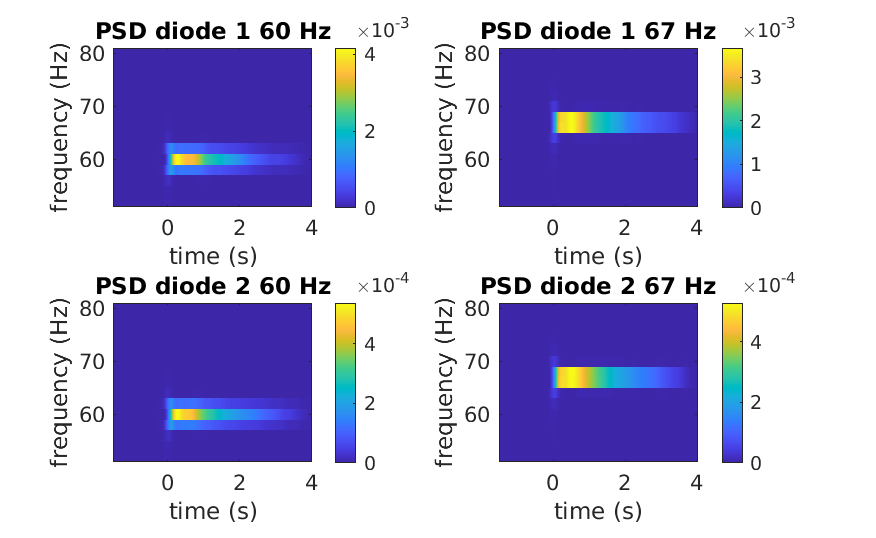

**4 Coherence multiplot**

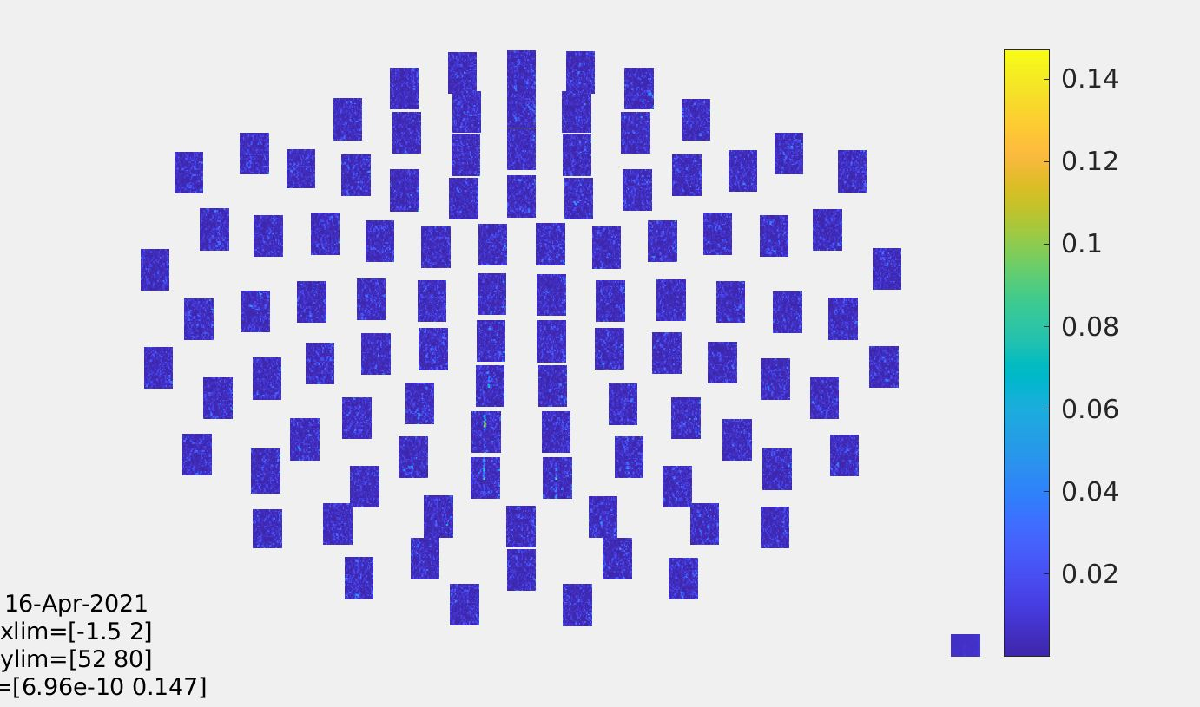

5 Coherence averaged over posterior SOI